# Birds at risk

Determine how many birds are at risk of collision with windturbine where and when.

## Setup

### Load data

Load windfarm data which has been processed (`windfram_processing.mlx`)

load('data/windfarms_processed.mat')
load('data/energy_processed.mat');

Load the grid of the bird density estimation

load('../2018/data/Density_estimationMap','g');

Load flow estimation (density and speed)

load('../2018/data/Density_estimationMap','gd');
load('../2018/data/Flight_estimationMap','guv');

Load the ratio map of altiudinal distribution of the bird

load('./data/ratio');

Add path

addpath('functions')

### Build other usefull data for later

define colormap

greens = interp1([1 128 256],[220, 233, 187;28, 155, 117;2, 76, 53]/255,1:256);
reds = interp1([1 128 256],[239, 220, 217;181, 57, 104;119, 38, 76]/255,1:256);
blues = interp1([1 128 256],[197, 221, 244;18, 122, 161;45, 66, 88]/255,1:256);

Compute area

dy = lldistkm([g.lat(1) g.lon(1)],[g.lat(2) g.lon(1)]);
dx = lldistkm([g.lat2D(:,1) g.lon2D(:,1)],[g.lat2D(:,1) g.lon2D(:,2)]);
area = repmat(dx*dy,1,g.nlon);

#### Create country map

bd = load('borderdata.mat');
inCountry=false(numel(g.lat),numel(g.lon),3);
ind = strcmp(bd.places,'France');
inCountry(:,:,1) = reshape(inpolygon(g.lon2D(:), g.lat2D(:), bd.lon{ind}', bd.lat{ind}'),size(g.lon2D));
ind = strcmp(bd.places,'Germany');
inCountry(:,:,2) = reshape(inpolygon(g.lon2D(:), g.lat2D(:), bd.lon{ind}', bd.lat{ind}'),size(g.lon2D));
ind =  strcmp(bd.places,{'Belgium'}) |  strcmp(bd.places,{'Netherlands'}) |  strcmp(bd.places,{'Luxembourg'});
inCountry(:,:,3) = reshape(inpolygon(g.lon2D(:), g.lat2D(:), [bd.lon{ind}]', [bd.lat{ind}]'),size(g.lon2D));

Illustration

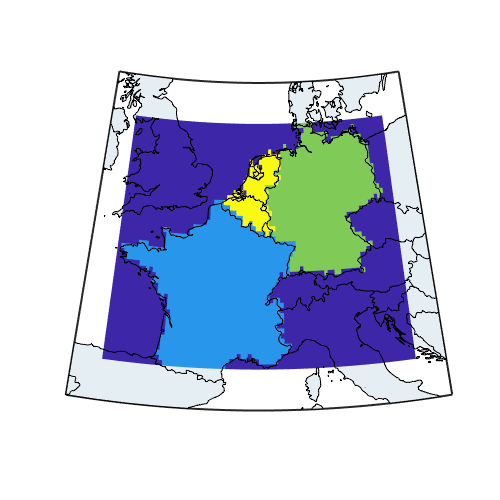

figure('position',[0 0 500 500]);  hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
surfm(g.lat,g.lon,sum(inCountry.*reshape(1:3,1,1,[]),3))
bordersm('countries','k');

#### Compute distance to coastline

load coastlines
dcoast = pdist2([g.lat2D(:) g.lon2D(:)],[coastlat coastlon], @lldistkm);
dcoast = reshape(min(dcoast,[],2),size(g.lat2D));

Illustration

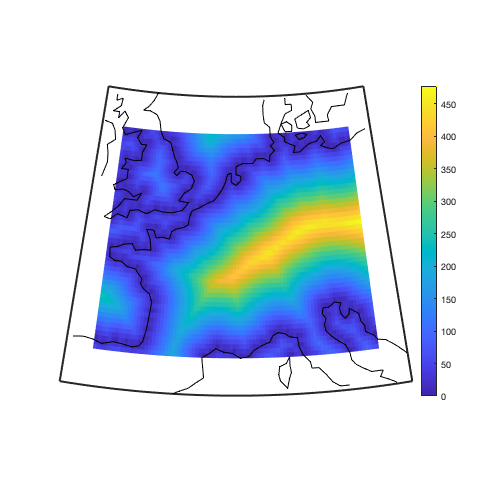

figure('position',[0 0 500 500]);  hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
surfm(g.lat,g.lon,dcoast)
plotm(coastlat,coastlon,'k');
colorbar

#### Define season

season = nan(size(time));
season(time<datetime('1-March-2018')|time>=datetime('1-Dec-2018'))=1;
season(time>=datetime('1-March-2018')&time<datetime('1-May-2018'))=2;
season(time>=datetime('1-May-2018')&time<datetime('1-Sep-2018'))=3;
season(time>=datetime('1-Sep-2018')&time<datetime('1-Dec-2018'))=4;

Illustration

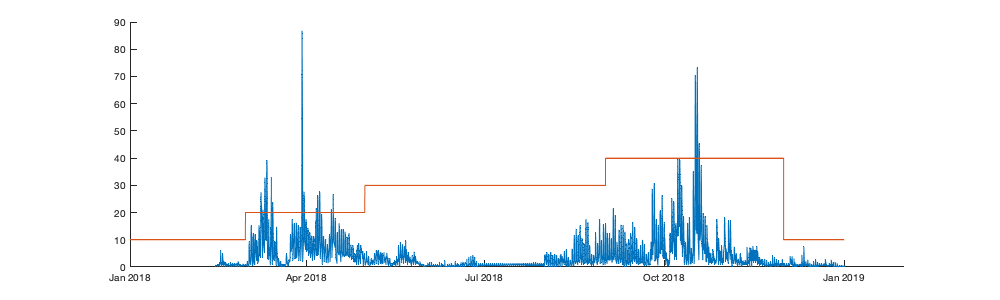

figure('position',[0 0 1000 300]); hold on;
plot(g.time,mean(gd.dens_est,'omitnan'))
plot(time,season*10)

#### Define night/day time

file='./data/ECMWF/2018_ssrdc.nc'; %ncdisp(file);
ssrdc = permute(flip(ncread(file,'ssrdc'),2) , [2 1 3]); 
daynight = ssrdc>40000;

## Construct turbine sweep area 

[G,ID] = findgroups(tim.grid_id);
turbineSweptArea=nan(1,g.nlm);
turbineSweptArea(ID) = splitapply(@nansum,tim.turbine_sweptArea.*tim.Number_of_turbines,G);
turbineSweptAreaMap = nan(size(g.latlonmask));
turbineSweptAreaMap(g.latlonmask) = turbineSweptArea;

Display data

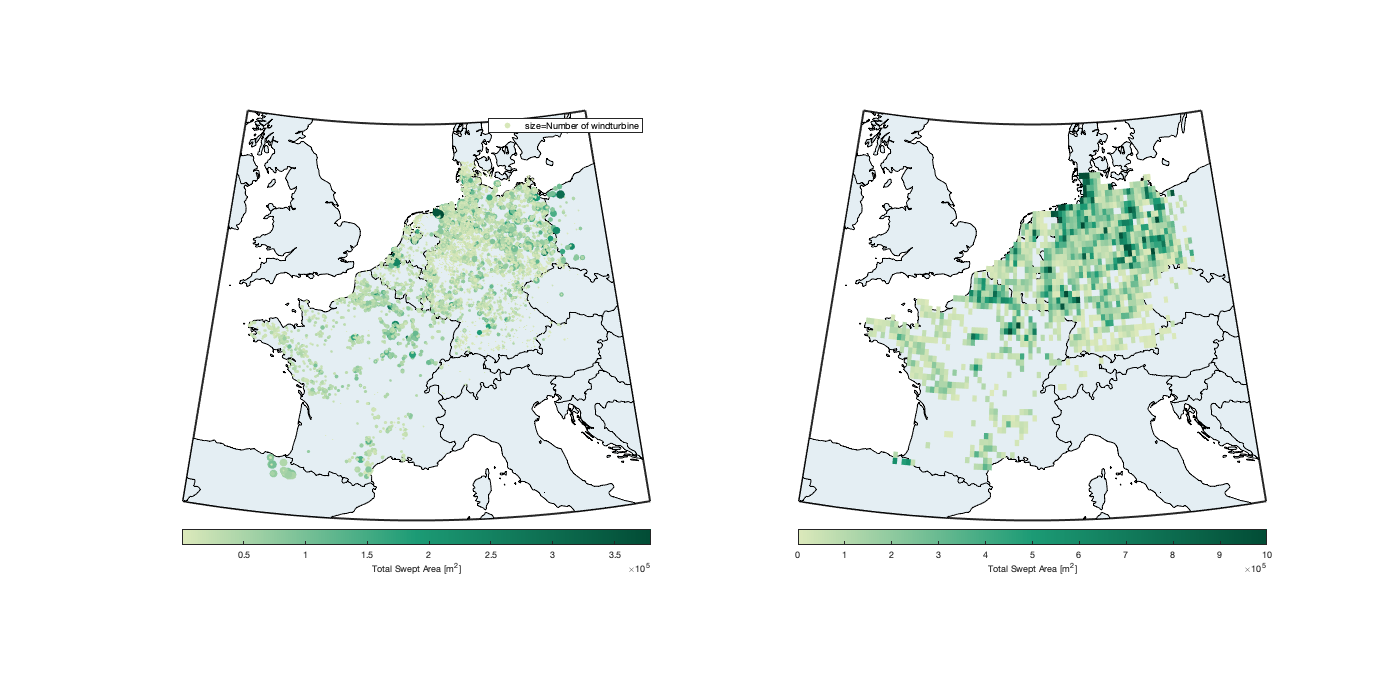

figure('position',[0 0 1400 700]); 
subplot(1,2,1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp = scatterm(tim.Latitude,tim.Longitude,tim.Number_of_turbines*2,tim.Number_of_turbines.*tim.turbine_sweptArea,'filled','MarkerFaceAlpha',.2);
c=colorbar('southoutside'); c.Label.String='Total Swept Area [m^2]';
legend(tmp,'size=Number of windturbine')
subplot(1,2,2); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
surfm(g.lat,g.lon,turbineSweptAreaMap)
c=colorbar('southoutside'); c.Label.String='Total Swept Area [m^2]';
% colormap(brewermap([],'YlGn')); 
colormap(greens); caxis([0 1000000])

Geographical characteristic 

tmp = table({'France','Germany','Benelux'}',...
[sum(area(inCountry(:,:,1))) ; sum(area(inCountry(:,:,2))) ; sum(area(inCountry(:,:,3)))],...
[sum(tim.Number_of_turbines(strcmp(tim.Country,'France'))); sum(tim.Number_of_turbines(strcmp(tim.Country,'Germany'))); sum(tim.Number_of_turbines(strcmp(tim.Country,'Netherlands')))+sum(tim.Number_of_turbines(strcmp(tim.Country,'Belgium')))+sum(tim.Number_of_turbines(strcmp(tim.Country,'Luxembourg')))],...
[nansum(turbineSweptAreaMap(inCountry(:,:,1))) ; nansum(turbineSweptAreaMap(inCountry(:,:,2))); nansum(turbineSweptAreaMap(inCountry(:,:,3)))],...
[sum(tim.Total_power(strcmp(tim.Country,'France'))); sum(tim.Total_power(strcmp(tim.Country,'Germany'))); sum(tim.Total_power(strcmp(tim.Country,'Netherlands')))+sum(tim.Total_power(strcmp(tim.Country,'Belgium')))+sum(tim.Total_power(strcmp(tim.Country,'Luxembourg')))],...
'VariableNames',{'Region','Region Area','Number of windturbine','Total Swept Area','Total Power'});
tmp.("Swept Area/Region Area") = tmp.("Total Swept Area") ./ tmp.("Region Area");
tmp

tmp = 3×6 table
      Region       Region Area    Number of windturbine    Total Swept Area    Total Power    Swept Area/Region Area
    ___________    ___________    _____________________    ________________    ___________    ______________________

    {'France' }    5.3129e+05              7614               4.7491e+07       1.6036e+07             89.388        
    {'Germany'}    3.5154e+05             30472               1.4878e+08       5.3427e+07             423.21        
    {'Benelux'}         68337              2640               1.4756e+07       5.1503e+06             215.93        


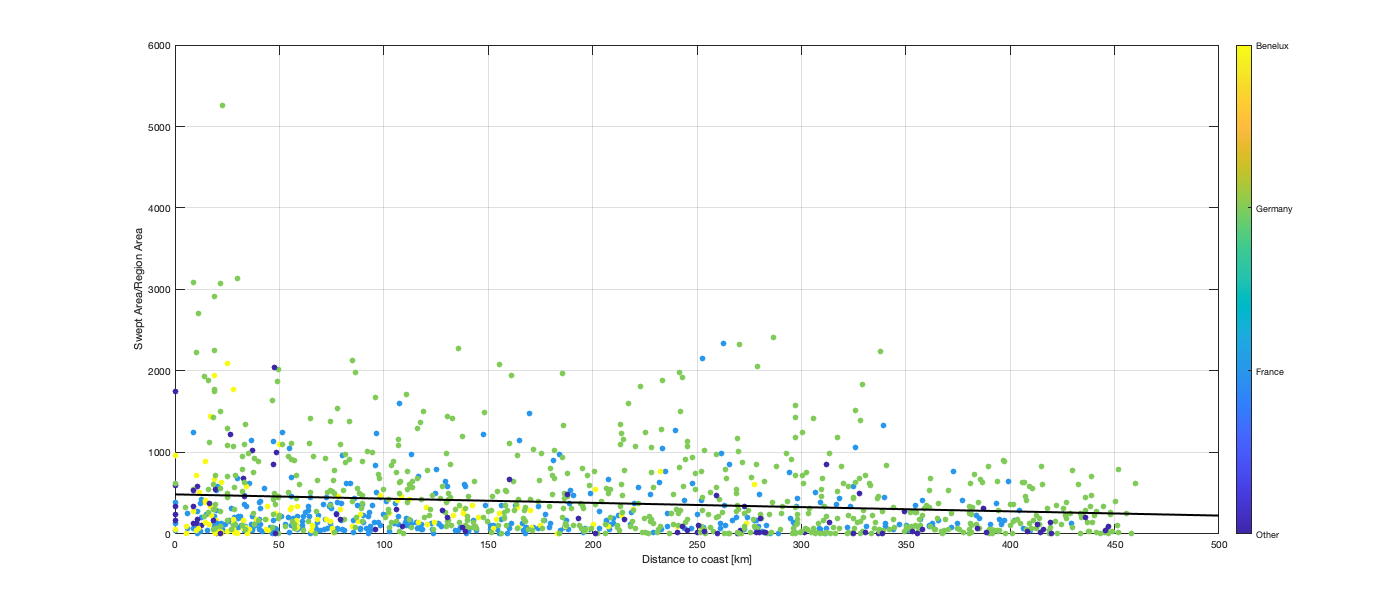

figure('position',[0 0 1400 600]);
scatter(dcoast(:),turbineSweptAreaMap(:)./area(:),[],reshape(sum(inCountry.*reshape(1:3,1,1,[]),3),1,[]),'filled'); l=lsline; l.Color='k'; l.LineWidth=2;
ylabel('Swept Area/Region Area'); xlabel('Distance to coast [km]')
c=colorbar; c.Ticks=0:3; c.TickLabels=['Other';tmp.Region]; box on; grid on;

## Bird at risk

We compute here the total number of bird at risk on the same grid (1hr, 0.25°)

### Interpolate the ratio on a grid

First, we compute the ratio of bird flying at windturbine height in time and space

g_ratio = predict(compactmdl, [repmat(g.lat2D(g.latlonmask),g.nt,1) repmat(g.lon2D(g.latlonmask),g.nt,1) g.NNT(:) repelem(datenum(g.time-g.time(1)),g.nlm,1) ones(numel(g.NNT(:)),2)]);
g_ratio = reshape(g_ratio,size(g.NNT));

Compute the standard deviation

g_ratio_std = polyval(p_abserror,gd.dens_est*1000);

Simulate value for the ratio

ratio_sim = g_ratio+normrnd(0,g_ratio_std);

Threashold the g_ratio to make sure no value are below zero.

g_ratio(g_ratio<0)=0;
g_ratio(g_ratio>1)=1;

For the simulated value, we project back the value on a symetry of zero to keep randomness

ratio_sim(ratio_sim<0)=0-ratio_sim(ratio_sim<0);

Illustration

figure('position',[0 0 800 300]);histogram(ratio_sim)
figure('position',[0 0 800 300]);histogram(ratio_sim)

### Compute birdflow

Then, we compute the bird flow [bird/m^2/hr] as

birdFlow_15min = nan(g.nlat,g.nlon,g.nt);
birdFlow_15min(repmat(g.latlonmask,1,1,g.nt)) = gd.dens_est * 1e-6 .* g_ratio .* sqrt(guv.u_est.^2 + guv.v_est.^2)*60*60; 

UNIT check: bird/km^2 * km^2/m^2 * - * 1/m * m/s * s/hr -> bird/m^2 * 1/m * m/hr -> bird/m^2/hr

### Downscale birdflow to 1hour

Convert time resolution of birdflow to match energy map. Average for the previous hour as wind is also the average over the previous hour.

[~,Locb]=ismember(dateshift(g.time,'end','hour'),time);
birdFlow = nan(g.nlat,g.nlon,numel(time));
for i=1:numel(time)
    birdFlow(:,:,i) = nanmean(birdFlow_15min(:,:,Locb==i),3);
end

We so the same for bird flight direction

birdDir_tmp = nan(g.nlat,g.nlon,g.nt);
birdDir_tmp(repmat(g.latlonmask,1,1,g.nt)) = angle(guv.u_est + 1i*guv.v_est);
birdDir = nan(g.nlat,g.nlon,numel(time));
for i=1:numel(time)
    birdDir(:,:,i) = meanangle(birdDir_tmp(:,:,Locb==i),3);
end
% histogram(abs(cos(wdir-birdDir)))

### Birds at Risk

Compute the bird at risk [bird/hr] as bird flow [bird/m^2/hr] x total swept area [m^2]. 

Suming require to divide by 4 because timstep is 15min (4 in 1 hours)

birdAtRisk = birdFlow .* turbineSweptAreaMap;
disp(['Total Number of bird at risk: ' num2str(round(nansum(birdAtRisk(:)/4))/1e6) ' Millions.'])

Total Number of bird at risk: 52.1155 Millions.


### Correction for wind direction map

First, the difference of wind direction and bird flight direction reduces the area with turbines base on the projection of swpt area plane perpendicular to bird direction (perp. to wind direction)

We first need to compute the windspeed u and v component seperatly

file='./data/ECMWF/2018_srf.nc'; %ncdisp(file);
w_time = datetime('2018-01-01 00:00'):1/24:datetime('2018-12-31 23:00'); % ncread(file,'time')
w_lat=flip(double(ncread(file,'latitude')));
w_lon=double(ncread(file,'longitude'));
w_u100 = permute(flip(ncread(file,'u100'),2) , [2 1 3]); 
w_v100 = permute(flip(ncread(file,'v100'),2) , [2 1 3]);
w_u10 = permute(flip(ncread(file,'u10'),2) , [2 1 3]); 
w_v10 = permute(flip(ncread(file,'v10'),2) , [2 1 3]);

we assume here a similar height accross space and time

height_mean = sum(tim.Hub_height.*tim.Number_of_turbines) ./ sum(tim.Number_of_turbines);

alpha = (log(w_u100)-log(w_u10)) ./ (log(100)-log(10));
wu_height = w_u100 .* (height_mean/100).^alpha;
alpha = (log(w_v100)-log(w_v10)) ./ (log(100)-log(10));
wv_height = w_v100 .* (height_mean/100).^alpha;

Fu = griddedInterpolant({w_lat,w_lon,datenum(w_time)},wu_height,'linear','nearest');
wu = Fu({g.lat,g.lon,datenum(time)});
Fv = griddedInterpolant({w_lat,w_lon,datenum(w_time)},wv_height,'linear','nearest');
wv = Fv({g.lat,g.lon,datenum(time)});

clear Fu Fv wv_height wu_height w_* alpha

Display data

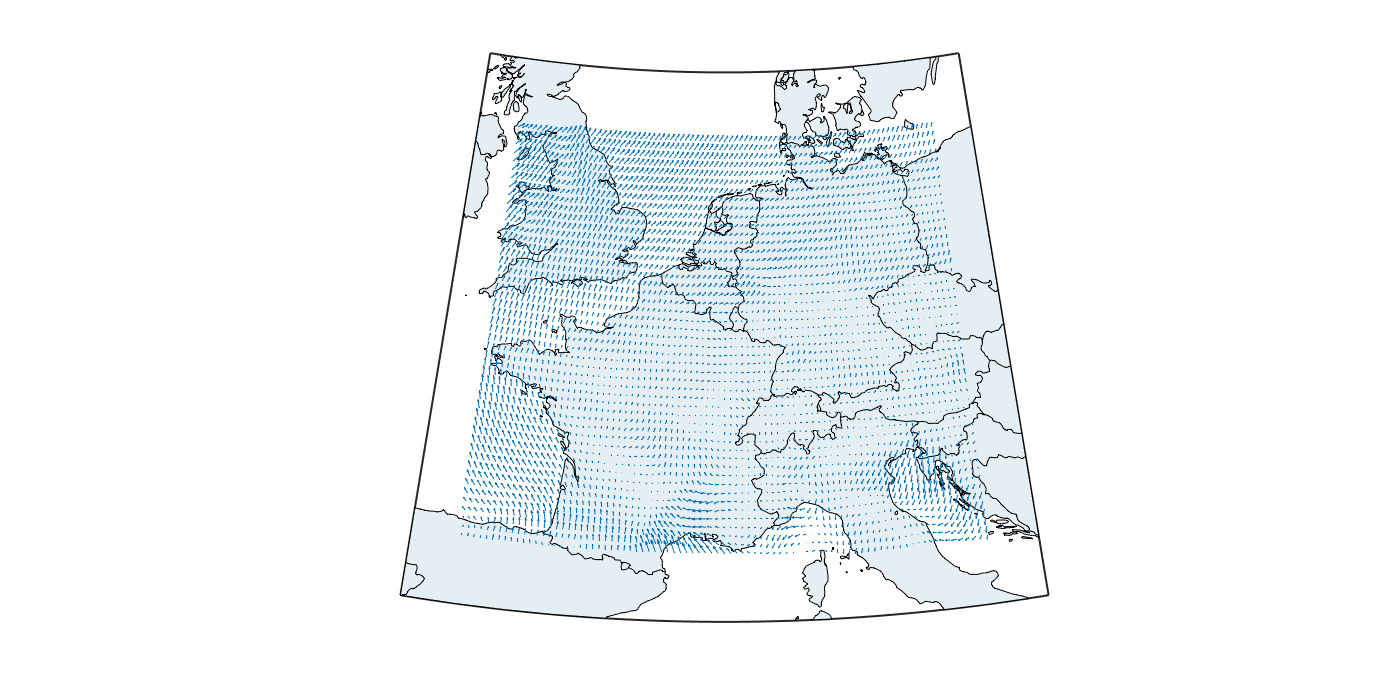

figure('position',[0 0 1400 700]);
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
quiverm(g.lat2D,g.lon2D,mean(wu,3),mean(wv,3))

Windwind day vs night characteristic

ws=abs(sqrt(wu.^2+wv.^2));
wdir = angle(wu + 1i*wv);
disp(['Day windspeed: M=' num2str(nanmean(ws(daynight))) ' | STD=' num2str(nanstd(ws(daynight))) ' | N=' num2str(sum(daynight(:)))])

Day windspeed: M=5.5024 | STD=3.568 | N=18170103


disp(['Night windspeed: M=' num2str(nanmean(ws(~daynight))) ' | STD=' num2str(nanstd(ws(~daynight))) ' | N=' num2str(sum(~daynight(:)))])

Night windspeed: M=6.1725 | STD=3.7193 | N=18315297


We can now compare the direction of the wind with the direction of the birds:

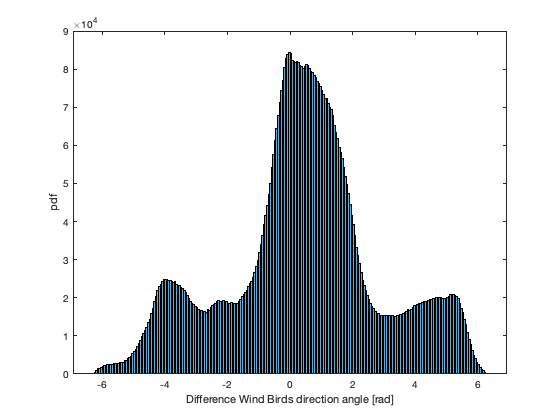

figure; histogram(wdir-birdDir); xlabel('Difference Wind Birds direction angle [rad]'); ylabel('pdf')

Finally we can update the bird of bird at risk using the cos of this angle difference

birdAtRisk = birdAtRisk .* abs(cos(wdir-birdDir));
disp(['Total Number of bird at risk: ' num2str(round(nansum(birdAtRisk(:)/4))/1e6) ' Millions.'])

Total Number of bird at risk: 33.5274 Millions.


### Correction for cut-in and cut-off

Second, we we assume a cut-in and cut-off of 2.4  and 24.1 m/s (see `1_windfarm_processing.html`). Based on the same smoothing of the windspeed within the time resolution of our data (1hr), we can estimate the probability of the windfarm to be off depending ofn the windspeed. We use that probability to reduce the bird at risk flow. 

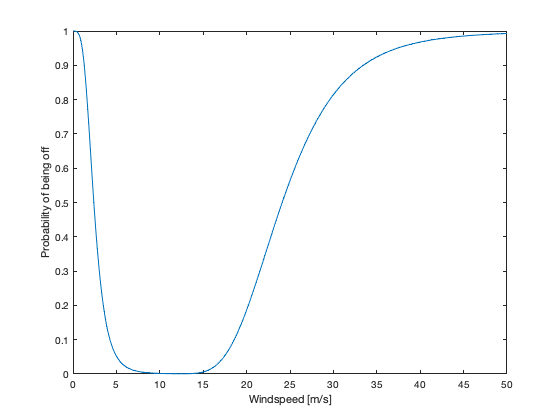

ws=0:.1:50;
pws = normcdf(2.4,ws,0.6+0.2*ws)+(1-normcdf(24.1,ws,0.6+0.2*ws));
figure; plot(ws,pws); xlabel('Windspeed [m/s]'); ylabel('Probability of being off')

birdAtRisk=birdAtRisk.*(1-interp1(ws,pws,abs((wu + 1i*wv))));
disp(['Total Number of bird at risk: ' num2str(round(nansum(birdAtRisk(:)/4))/1e6) ' Millions.'])

Total Number of bird at risk: 28.5209 Millions.


## Illustrations

### Over time

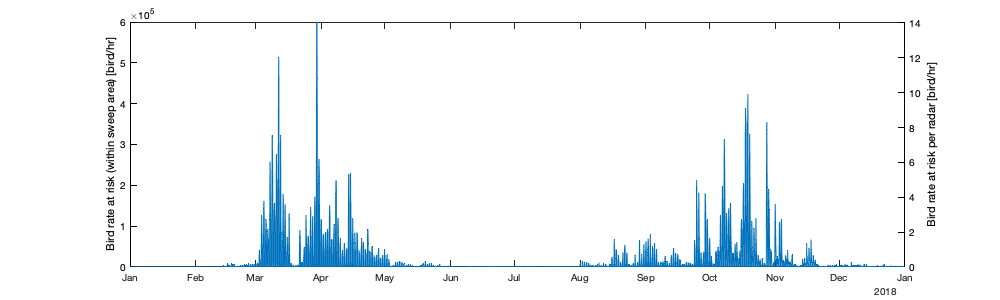

figure('position',[0 0 1000 300]); 
plot(time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]));
ylim([0 6e5]);ylabel('Bird rate at risk (within sweep area) [bird/hr]')
yyaxis 'right'
ax = gca; ax.YAxis(2).Color = 'k';
ylim([0 6e5]/nansum(tim.Number_of_turbines)); ylabel('Bird rate at risk per radar [bird/hr]')

### Over space

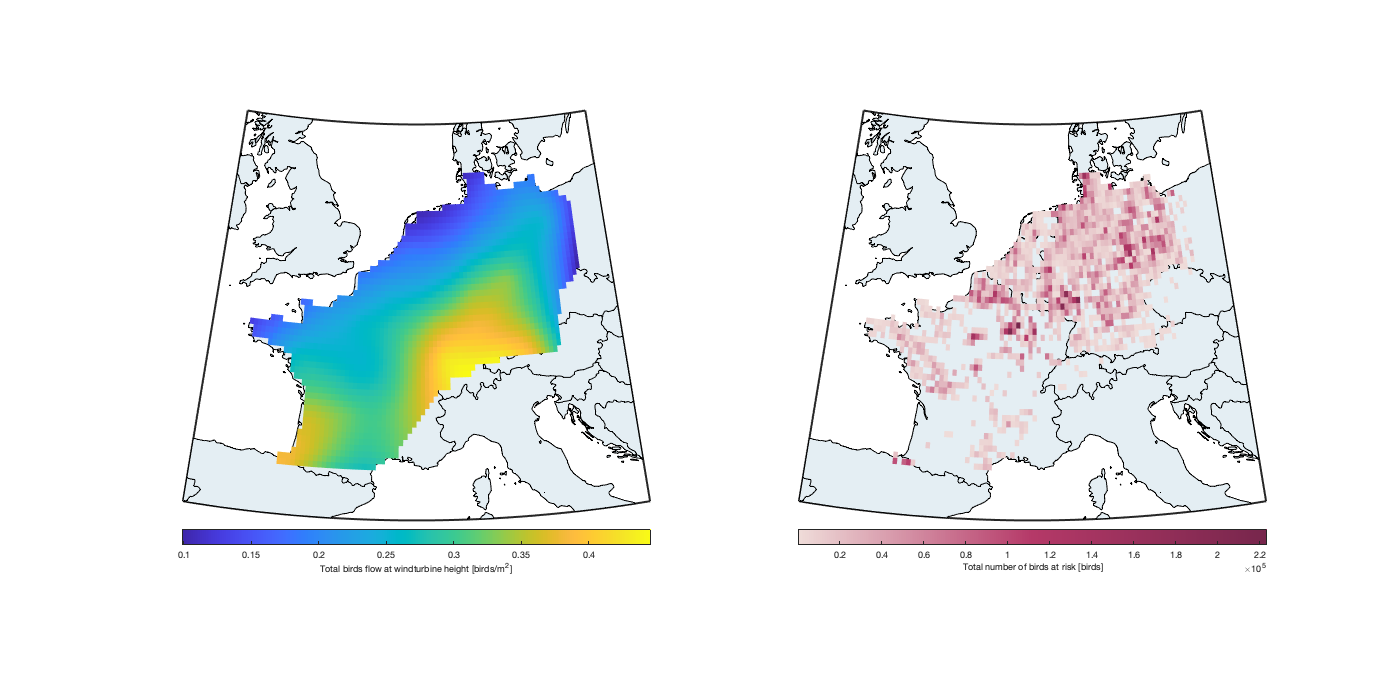

figure('position',[0 0 1400 700]); 
subplot(1,2,1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp = nansum(birdFlow/4,3); % birds/hr/m^2 -> birds/m^2 (resolution of 15min)
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
c=colorbar('southoutside'); c.Label.String='Total birds flow at windturbine height [birds/m^2]';
ax=subplot(1,2,2);hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp = nansum(birdAtRisk/4,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
c=colorbar('southoutside'); c.Label.String='Total number of birds at risk [birds]';
% colormap(ax,brewermap([],'OrRd'))
 colormap(ax,reds);

### Per countries

birdAtRisk_tmp = birdAtRisk;
birdAtRisk_tmp(~repmat(inCountry(:,:,1),1,1,size(birdAtRisk,3)))=0;
birdAtRisk_time(:,1) = reshape(nansum(nansum(birdAtRisk_tmp,1),2),[],1);

birdAtRisk_tmp = birdAtRisk;
birdAtRisk_tmp(~repmat(inCountry(:,:,2),1,1,size(birdAtRisk,3)))=0;
birdAtRisk_time(:,2) = reshape(nansum(nansum(birdAtRisk_tmp,1),2),[],1);

birdAtRisk_tmp = birdAtRisk;
birdAtRisk_tmp(~repmat(inCountry(:,:,3),1,1,size(birdAtRisk,3)))=0;
birdAtRisk_time(:,3) = reshape(nansum(nansum(birdAtRisk_tmp,1),2),[],1);


round(splitapply(@sum,birdAtRisk_time,season')/10^6,2)'

ans =     0.5900   15.8100    1.6700   13.7800
    0.7500   36.8400    3.2100   30.6300
    0.1600    3.2000    0.2100    2.9900


sum(birdAtRisk_time)/10^6

ans =    31.8462   71.4300    6.5612


### Per radar

Map of turbine number

[G,ID] = findgroups(tim.grid_id);
turbineNb=nan(1,g.nlm);
turbineNb(ID) = splitapply(@nansum,tim.Number_of_turbines,G);
turbineNbMap = nan(size(g.latlonmask));
turbineNbMap(g.latlonmask) = turbineNb;

Map of total bird at risk

tmp = nansum(birdAtRisk/4,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan;

average number of bird at risk per windturbine

mean(tmp./turbineNbMap,'all','omitnan')

ans = 794.0556

## Compute uncertainty

Run on UNIL server

% rar = nan(g.nt,500);

prepare the birdrisk template (just need to multiply by density

% birdAtRisk_t = nan(g.nlat,g.nlon,g.nt);
% birdAtRisk_t(repmat(g.latlonmask,1,1,g.nt)) = turbineSweptArea' * 1e-6 .* g_ratio / (windturbine_maxheight-windturbine_minheight)  .* sqrt(guv.u_estim.^2 + guv.v_estim.^2)*60*60; 

Loop through all files

% for ii=1:5
%     load(['D:\Guests\rafnuss_at_gmail_com\tmp_BMM2018\Density_simulationMap_reassemble_' num2str(ii)]);
%     for i_real = 1:size(real_dens,4)
%         rar(:, (ii-1)*100+i_real) = reshape(nansum(nansum(birdAtRisk_t .* real_dens(:,:,:,i_real),1),2),1,[]);
%     end
% end

Save

% save('data/BirdAtRisk_sim','rar')

Load

load('data/BirdAtRisk_sim')

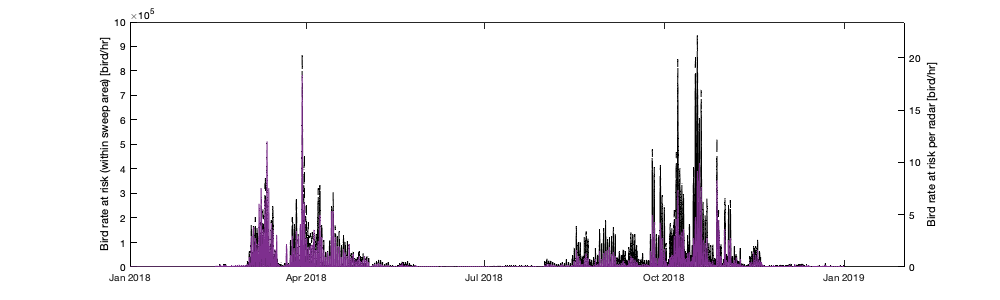

figure('position',[0 0 1000 300]);  hold on;
plot(g.time,nanmean(rar,2),'k')
plot(g.time,quantile(rar,.1,2),'--k')
plot(g.time,quantile(rar,.9,2),'--k')
plot(time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]),'LineWidth',0.1);

ylim([0 1e6]);ylabel('Bird rate at risk (within sweep area) [bird/hr]')
yyaxis 'right'
ax = gca; ax.YAxis(2).Color = 'k'; box on
ylim([0 1e6]/nansum(tim.Number_of_turbines)); ylabel('Bird rate at risk per radar [bird/hr]')

## Compute Power Production on a map

Put the power on a grid

tmp=nan(g.nlm,numel(time));
for i_ll=1:g.nlm
    id = tim.grid_id==i_ll;
    tmp(i_ll,:) = nansum(power(id,:),1);
    % tmp(i_ll,:) = nansum(max(tim.powerCurve(id,:),[],2).*tim.Number_of_turbines(id));
end
energy=nan(g.nlat,g.nlon,numel(time));
energy(repmat(g.latlonmask,1,1,numel(time))) = tmp*1000*60*60; % convert kW -> J
% plot(max(power'),tim.turbine_capacity.*tim.Number_of_turbines,'.k')

Put turbine Capacity and Number of turbine on a map

[G,ID] = findgroups(tim.grid_id);
tmp=nan(1,g.nlm);
tmp(ID) = splitapply(@nansum,tim.turbine_capacity.*tim.Number_of_turbines,G);
capacityMap = nan(size(g.latlonmask));
capacityMap(g.latlonmask) = tmp;
% tmp=nan(1,g.nlm);
% tmp(ID) = splitapply(@nansum,tim.Number_of_turbines,G);
% turbineNumberMap = nan(size(g.latlonmask));
% turbineNumberMap(g.latlonmask) = tmp;

Display data

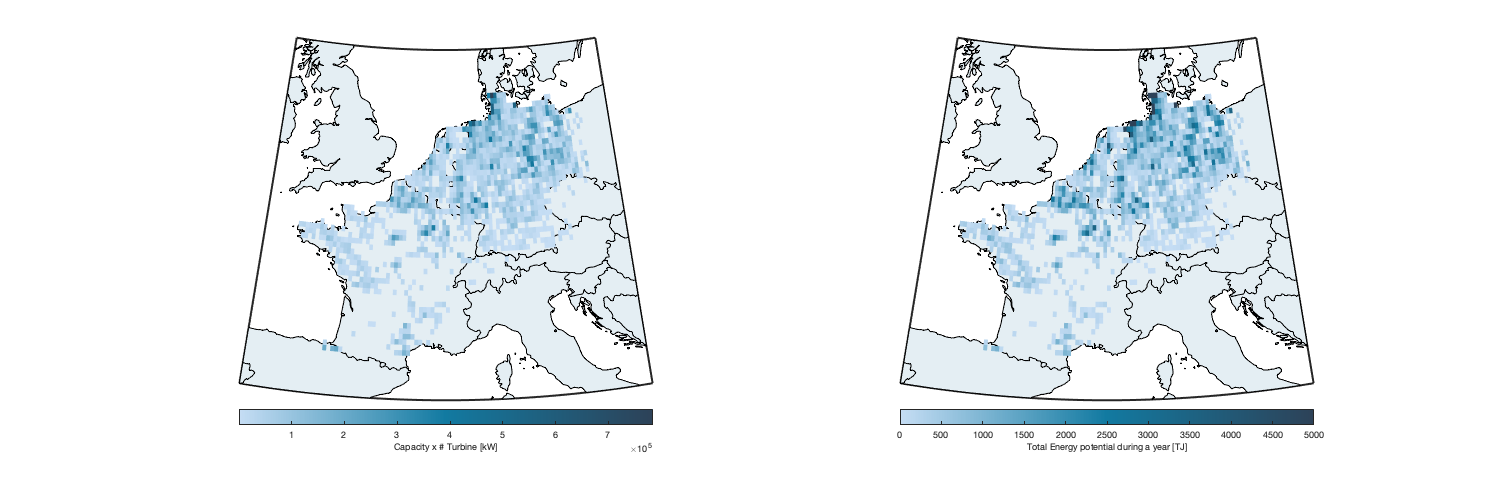

figure('position',[0 0 1500 500]); 
subplot(1,2,1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
surfm(g.lat,g.lon,capacityMap)
c=colorbar('southoutside'); c.Label.String='Capacity x # Turbine [kW]';
subplot(1,2,2); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp = nansum(energy,3); % 
tmp(tmp==0)=nan; 
surfm(g.lat,g.lon,tmp/1e12)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('southoutside'); c.Label.String='Total Energy potential during a year [TJ]';
caxis([0 5e3])
% colormap(plasma)
colormap(blues)

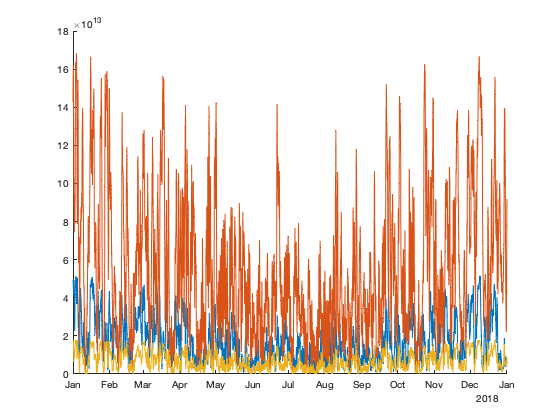

energy_tmp = energy;
energy_tmp(repmat(~inCountry(:,:,1),1,1,size(energy,3)))=0;
energy_time(:,1) = reshape(nansum(nansum(energy_tmp,1),2),[],1);

energy_tmp = energy;
energy_tmp(repmat(~inCountry(:,:,2),1,1,size(energy,3)))=0;
energy_time(:,2) = reshape(nansum(nansum(energy_tmp,1),2),[],1);

energy_tmp = energy;
energy_tmp(repmat(~inCountry(:,:,3),1,1,size(energy,3)))=0;
energy_time(:,3) = reshape(nansum(nansum(energy_tmp,1),2),[],1);

figure; hold on;
plot(time, energy_time)

round(splitapply(@sum,energy_time,season')/10^15)'

ans =     51    28    31    36
   160    86   110   122
    20    11    13    15


## Combine Bird at Risk and Energy

% birdAtRiskPerEnergy = birdAtRisk./energy;

Plot

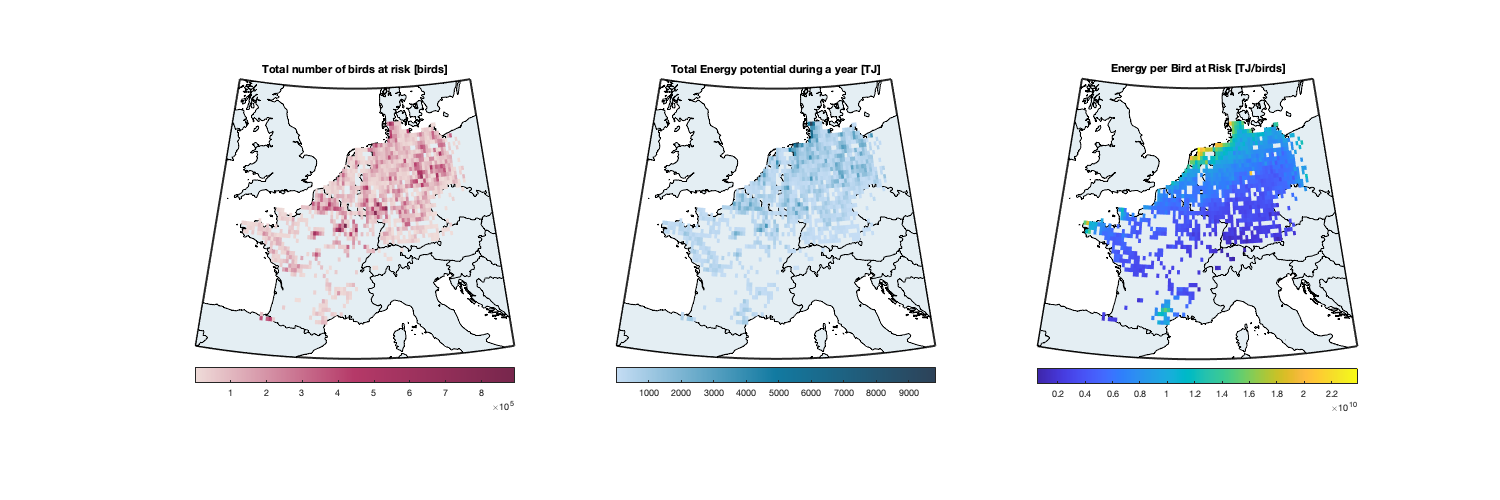

figure('position',[0 0 1500 500]); 
ax1=subplot(1,3,1);hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp = nansum(birdAtRisk,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
c=colorbar('southoutside'); title('Total number of birds at risk [birds]');
colormap(ax1,reds);%colormap(ax1,brewermap([],'OrRd'))

ax2=subplot(1,3,2); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp2 = nansum(energy,3); % 
tmp2(tmp2==0)=nan; 
surfm(g.lat,g.lon,tmp2/1e12)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('southoutside'); title('Total Energy potential during a year [TJ]');
colormap(ax2,blues); %caxis([0 5e27]); colormap(ax2,plasma)

ax3=subplot(1,3,3); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
surfm(g.lat,g.lon,tmp2./tmp)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('southoutside'); title('Energy per Bird at Risk [TJ/birds]');

% colormap(ax3,viridis)

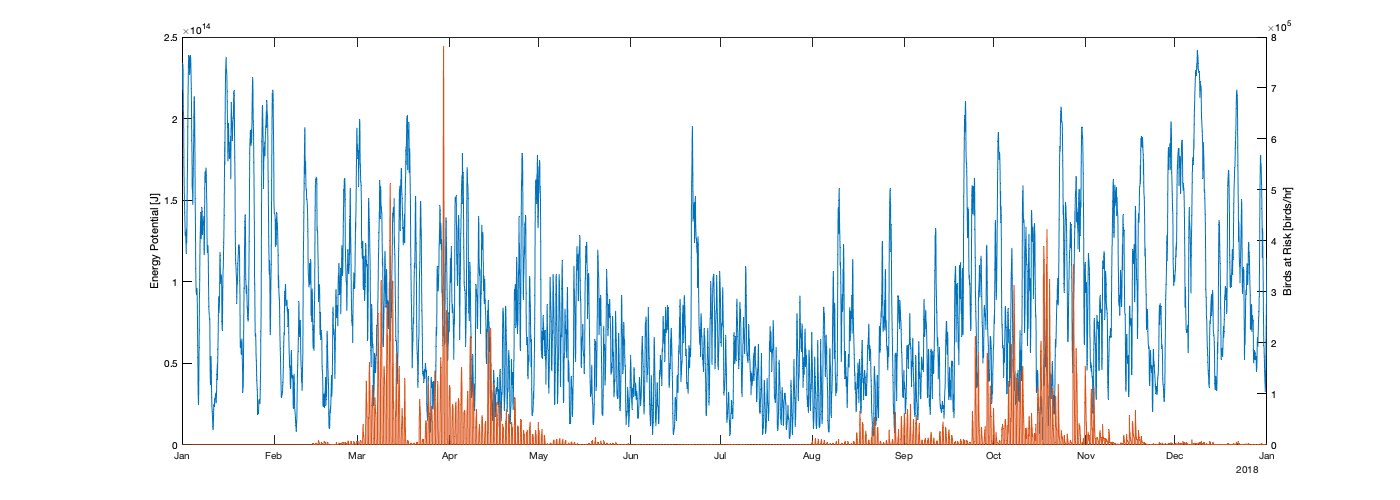

figure('position',[0 0 1400 500]); 
plot(time,reshape(nansum(nansum(energy,1),2),1,[]))
ylabel('Energy Potential [J]')
yyaxis right
plot(time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]))
ylabel('Birds at Risk [birds/hr]')
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';

## Save

save('data/birdAtRisk.mat','birdAtRisk','energy','daynight','birdFlow','birdDir','wdir','ws');